# Numerical Integration Using Trapezoidal Method

*Pouria Motahhari, Chemical and Petroleum Engineering Department, Fall 2022*

Numerical integration is a fundamental tool in mathematics, engineering, and scientific computing, enabling the approximation of definite integrals for a wide range of functions. This document explores the implementation of numerical integration using MATLAB, with a specific focus on the Trapezoidal Rule. The code provided calculates the integral of a user-defined function over a specified interval and offers a comparison with the analytical integral value. Whether you are a student studying numerical methods or a professional seeking to apply numerical integration in practical applications, this document provides a clear explanation of the MATLAB code's functionality and its potential for customization to suit your integration needs.

The trapezoidal numerical integration method is a fundamental approach in calculus and numerical analysis. It approximates definite integrals by dividing the area under a curve into trapezoids. Widely used in various fields, it offers a straightforward means of estimating integrals, making it a versatile tool in solving real-world problems involving continuous functions. 

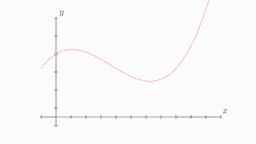

*An animation that shows what the trapezoidal rule is and how the error in approximation decreases as the step size decreases - *[*Source*](https://en.wikipedia.org/wiki/Trapezoidal_rule)

For a function like $f\left(x\right)=x^4 -5x^3 +6x^2 +4x+\sin \left(2-x\right)-5$, we have to proceed these steps:

### Part1: Input data

clc, clear       % Clearing Workspace & Command Window
syms x
f(x)= input('Enter the equation of function: ');   %This is a sample continuous function. you can change this function.
x_l= input('Enter the lower bound value:');   %This is a sample. you can change lower bounds.
x_u= input('Enter the upper bound value:');   %This is a sample. you can change upper bounds.
x_c=linspace(x_l,x_u); %simple vector for plotting

### Part2: Actual Integral equation & value

actual_int=int(f);
disp("function's intergral is: "), disp( actual_int )

function's intergral is: 


$$\cos\left(x-2\right)-5\,x+2\,x^{2}+2\,x^{3}-\frac{5\,x^{4}}{4}+\frac{x^{5}}{5}$$

actual_int_val=double( actual_int(x_u)-actual_int(x_l) );
disp('Actual value of integral is: '), disp( actual_int_val )

Actual value of integral is: 
    4.5011



### Part3: Numeric Integral calulation

The Trapezoidal integral derived using the following equation:


$$\int_{x_1 }^{x_2 } f\left(x\right)\ldotp \mathrm{dx}=\frac{\left(f\left(x_2 \right)+f\left(x_1 \right)\right)}{2}\times \left(x_2 -x_1 \right)$$


h=x_u-x_l; %integration interval
trape_int=double( f(x_l) + f(x_l+h) ) *h/2;
disp('2 Point trapezius integration answer is: '), disp(trape_int)

2 Point trapezius integration answer is: 
    3.4563



disp(['ERROR= ', num2str( trape_int-actual_int_val )])

ERROR= -1.0448


### Part4: Visualization

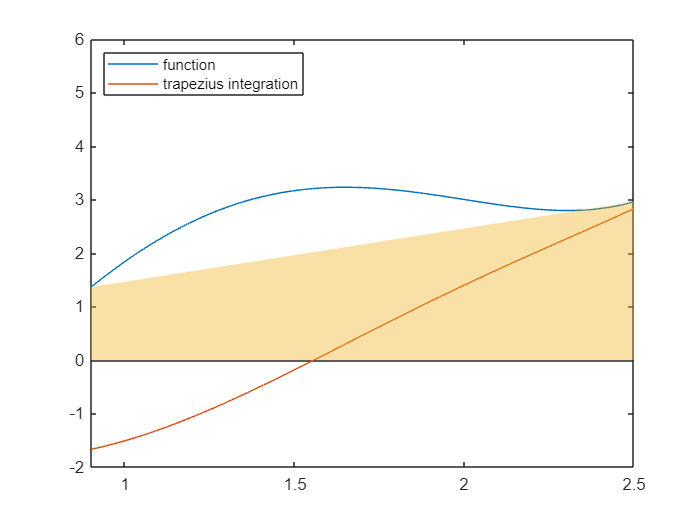

fplot(f)
hold on 
fplot(actual_int)
legend({'function','analytical integral of function'},'Location','northwest')
xlim([x_l x_u])
ylim([-2 6])

area( [x_l,x_u], double([f(x_l),f(x_u)]), "FaceAlpha", 0.4, "LineStyle","none" )
legend({'function','trapezius integration'},'Location','northwest')
xlim([x_l x_u])
ylim([-2 6])